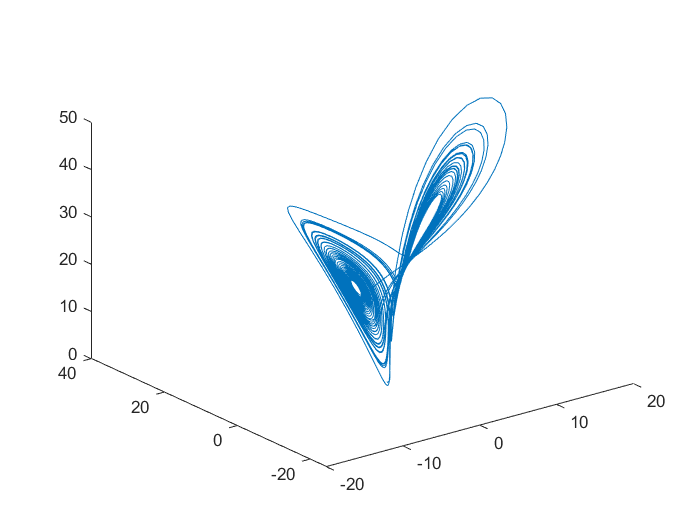

clear;clc;close all;

% ode45
x0 = [0, 1, 0];
[~, sol] = ode45(@Lorenz, [0 50], x0);
figure
plot3(sol(:, 1), sol(:, 2), sol(:, 3));

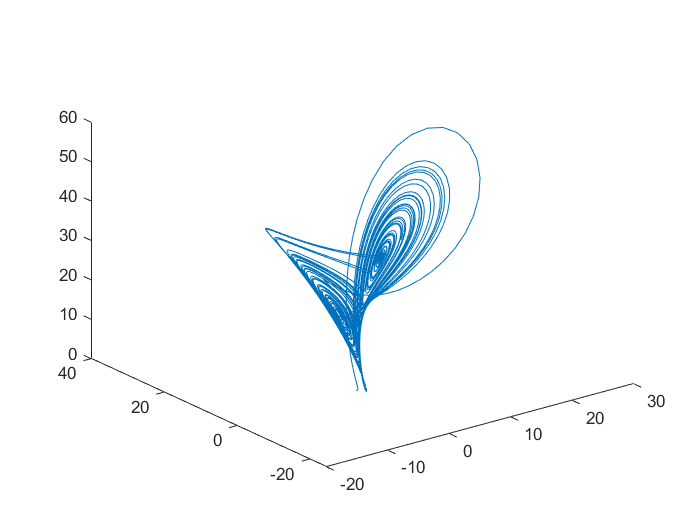


% Euler
func = @(t, Y) [10*(Y(2) - Y(1)), Y(1)*(28 - Y(3)) - Y(2), Y(1)*Y(2) - 8/3*Y(3)];
dh = 0.01;
t = 0:dh:50;
N = length(t);
X_Euler = zeros(N, 3);
x0 = [0, 1, 0];
X_Euler(1, :) = x0;
for i = 1:N-1
    dx = func(t(i), X_Euler(i, :));
    X_Euler(i+1, :) = X_Euler(i, :) + dh*dx;
end
figure
plot3(X_Euler(:, 1), X_Euler(:, 2), X_Euler(:, 3));

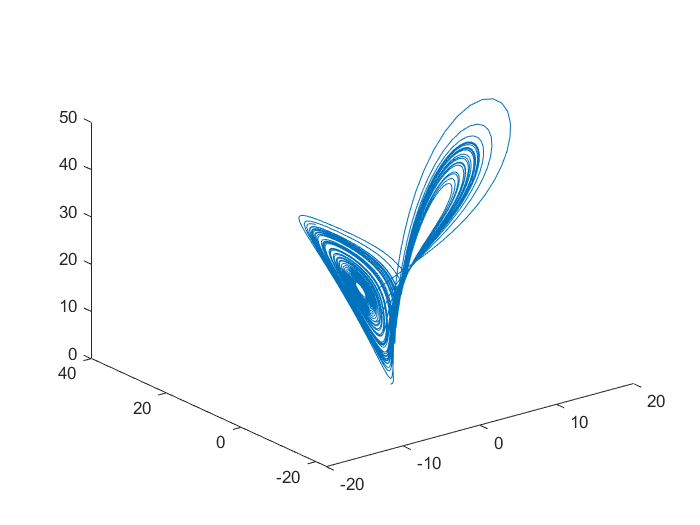


% improved Euler
X_imEuler = zeros(N, 3);
X_imEuler(1, :) = x0;
for i = 1:N-1
    dx1 = func(t(i), X_imEuler(i, :));
    dx2 = func(t(i), X_imEuler(i, :) + dh*dx1);
    X_imEuler(i+1, :) = X_imEuler(i, :) + dh*(dx1 + dx2) / 2;
end
figure
plot3(X_imEuler(:, 1), X_imEuler(:, 2), X_imEuler(:, 3));

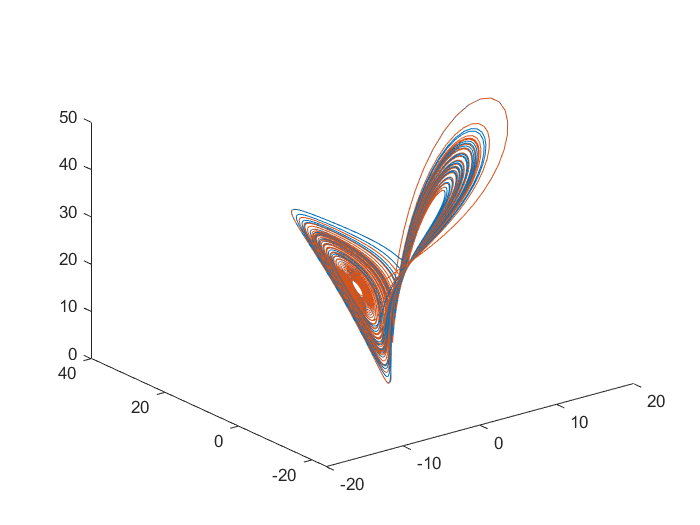


% Runge-Kutta
x0 = [0.0001, 1, 0];
X_RK = zeros(N, 3);
X_RK(1, :) = x0;
for i = 1:N-1 
    K1 = func(t(i), X_RK(i, :));
    K2 = func(t(i) + dh/2, X_RK(i, :) + (dh/2)*K1);
    K3 = func(t(i) + dh/2, X_RK(i, :) + (dh/2)*K2);
    K4 = func(t(i) + dh, X_RK(i, :) + dh*K3);
    X_RK(i+1, :) = X_RK(i, :) + (dh/6)*(K1 + 2*K2 + 2*K3 + K4);    
end
figure
plot3(X_RK(:, 1), X_RK(:, 2), X_RK(:, 3));
x0 = [0, 1, 0];
X_RK = zeros(N, 3);
X_RK(1, :) = x0;
for i = 1:N-1 
    K1 = func(t(i), X_RK(i, :));
    K2 = func(t(i) + dh/2, X_RK(i, :) + (dh/2)*K1);
    K3 = func(t(i) + dh/2, X_RK(i, :) + (dh/2)*K2);
    K4 = func(t(i) + dh, X_RK(i, :) + dh*K3);
    X_RK(i+1, :) = X_RK(i, :) + (dh/6)*(K1 + 2*K2 + 2*K3 + K4);    
end
hold on
plot3(X_RK(:, 1), X_RK(:, 2), X_RK(:, 3));
hold off

function  eqn = Lorenz(~, var)
x = var(1);
y = var(2);
z = var(3);
eqn = [10*(y - x), x*(28 - z) - y, x*y - 8/3*z]';
end